Cargar la imagen

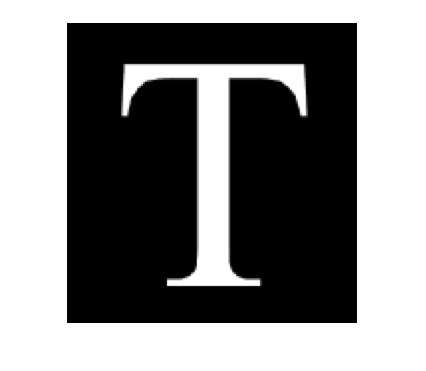

I = imread("imageT.png");
G = rgb2gray(I);
imshow(G);

Identidad

[x, y] = size(G);
Img_Identidad = zeros(x, y);
identidad = [1 0 0;
           0 1 0;
           0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * identidad;
        Img_Identidad(coord(1), coord(2)) = G(i,j);
    end
end
imshow(Img_Identidad);

Escalado

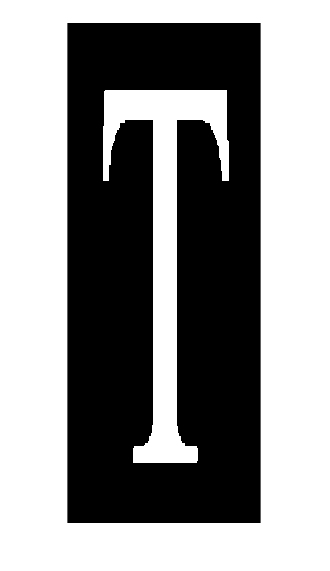

Cx = 5; Cy=2;

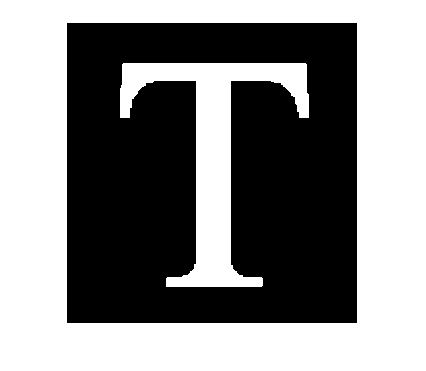

[x, y] = size(G);
Img_Scale = zeros(x*Cx, y*Cy);
scaling = [Cx 0 0;
           0 Cy 0;

           0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * scaling;
        Img_Scale((coord(1)-Cx+1):coord(1), (coord(2)-Cy+1):coord(2)) = G(i,j);
    end
end
imshow(Img_Scale);

Identidad

% Cx = 5; Cy=2;


Traslación

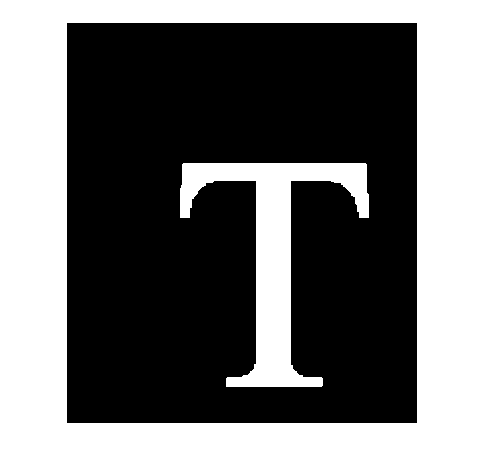

tx = 100; ty=60;

[x, y] = size(G);
Img_Traslation = zeros(x+tx, y+ty);
traslation = [1 0 0;
              0 1 0;
              tx ty 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * traslation;
        Img_Traslation(coord(1), coord(2)) = G(i,j);
    end
end
imshow(Img_Traslation);

Rotacion

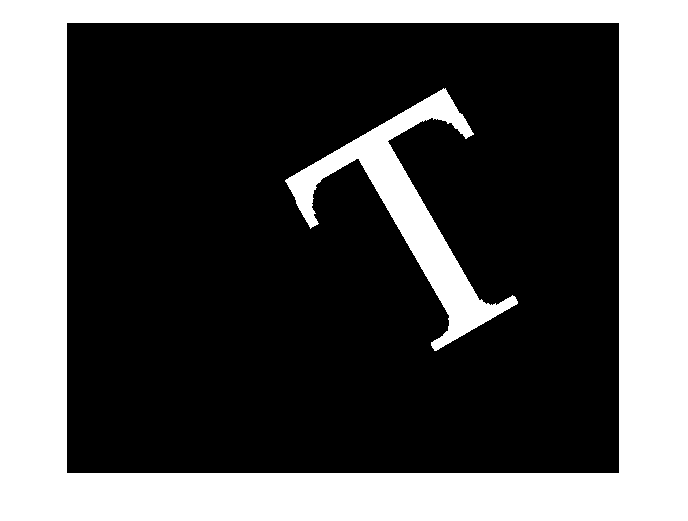

tx = 150; ty = 150;

tetha = pi/6;
seno = sin(tetha);
coseno = cos(tetha);
[x, y] = size(G);
Img_Rotacion = zeros(x+tx, y+ty);
rotacion = [coseno seno 0;
           -seno coseno 0;
                tx ty 1];
for i=1:x
    for j=1:y
        coord = ([i j 1] * rotacion);
        Img_Rotacion(round(coord(1)):round(coord(1))+1, round(coord(2)):round(coord(2))+1) = G(i,j);
    end
end
imshow(Img_Rotacion);